# Clearance

clc;
clear;
close all;

## VARIABLES

M = 16;       % Mic Number
L = 0.45;     % [m] Total Array Length
Fs = 8*1e3;   % [Hz] sampling frequency
c = 343;      % [m/s] speed of sound
d = L/(M-1);  % [m] mic distance

% anti-aliasing
max_freq = c/(2*d); % maximum carrier frequency
        %Here, max_freq~=5.7*10^3 Hz, and Nyquist frequency is fs/2 = 4 kHz


% stft window
Sz = 256;           % [samples] size of the rectangular window
Hop = 1;            % [samples] hopsize
fft_len = 1024;
theta_axis = -90:1:90;
theta_rad_axis = 0 : 2*pi/180 :  pi ;

%Adding the d<=lambda/2 condition with lambda the wavelength of the source
%signal --> STFT --> fc identification --> lambda computation --> checking
%if d = L/(M-1) <lambda/2

## FUNCTIONS

function [freqs, time_axis, freq_axis] = MyStft(in, samp_freq, wlen, fft_len, plotme) 
    %{
    Arg in : audiofile to analyze dimensions [len, n_chans]
    Arg samp_freq : sampling frequency we'll be using in Hz
    Arg wlen : length in samples of the window
    Arg fft_len : length of the total FFT, which will be halved at the end
                    to stay below Nyquist frequency

    Here, we are performing unitary hop size STFT

    Arg verbose : boolean flag to require plots
    Out freqs : 3D array containing, for each microphone source, the
                content of the fft of in for each applied window
    Out time_axis : array of dimension [1, num_wd] used to generate the
                    adequate time axis
    Out freq_axis : array of dimension [1, num_freq] used to generate the
                    adequate frequency axis, once again, num_freq is half the fft_len
                    (Nyquist frequency)
    %}   

    [len, n_chans] = size(in); 

    if (len < wlen)
        error("the input signal is shorter than the window ! ");
    end

    num_wd = floor(len-wlen)+1;

    in_trans = in.';
    y = zeros(fft_len, num_wd, n_chans);

    for i = 1:num_wd
        used_samps = i:i+wlen-1;            % range of application of the window
        wind_in = in_trans(:, used_samps);  % applying rectangular windowing on each channel

        freq_in = fft(wind_in, fft_len, 2); %Performing the STFT allong the columns of wind_in
        y(:,i,:) = freq_in.';               % the result is transposed to get the time on the rows
    end

    time_axis = (0:1:num_wd-1) * wlen/samp_freq;     % generating the time axis of the stft in ms
    %time_axis = (0:1:num_wd-num_wd/samp_freq) * 1/samp_freq;               
    freq_axis = 0 : samp_freq/fft_len : (samp_freq-samp_freq/fft_len)/2;    % generating the frequency axis of the stft, until Nyquist frequency
    freqs = y(1 : fft_len/2 , :, :);                                        % sampling theorem

    if plotme==true
        figure();
        for i = 1:size(freqs, 3)  %Sweeping through the different channels
            subplot(2, 8, i);
            imagesc(time_axis, freq_axis, abs(freqs(:, :, i)));
            axis xy;
            ylim([0 500]);
            title(sprintf("Channel %d", i));
            xlabel("Time (ms)");
            ylabel("Frequency (Hz)");
        end
        sgtitle(sprintf("STFT of each mic signal, wlen = %d & fft_ len = %d", wlen, fft_len));
    elseif plotme == false
        disp("No plots required");
    else 
        error("Unrecognized verbose plotme");
    end

end

## File extraction

[y, fs] = audioread("array_recordings.wav");

index_max_freq = floor( (max_freq/fs) * (fft_len) ) ; % index equivalent to the value of max_freq

stop = floor(length(y)/100);


%%[spectrum, time, freq] = MyStft( y( 1 : stop, :), fs, Sz, fft_len, true);
% Extract the STFT results for each microphone channel

## Temporary

%{
figure();
axis tight manual;  % Fix the axis limits
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Evolution of FFT in Time');

% Preallocate data for animated plot
num_steps = 200;
step_len = floor(size(y, 1) / num_steps);
f = linspace(0, fs/2, fft_len/2);

figure();
for i = 1:num_steps
    disp(['window #' int2str(i)]);
    data_segment = y((i-1)*step_len+1 : i*step_len, :);
    
    % Compute STFT
    [spectrum, time_axis, freq_axis]  = MyStft(data_segment, fs, Sz, fft_len, false);
    
    % Compute average magnitude spectrum
    %avg_spectrum = mean(abs(spectrum), 3);
    %fft_avg = avg_spectrum(:, 1);

    for j = 1:size(spectrum, 3)  %Sweeping through the different channels
            hold off;
            subplot(2, 8, j);
            imagesc(time_axis, freq_axis, abs(spectrum(:, :, j)));
            axis xy;
            ylim([0 500]);
            title(sprintf("Channel %d", j));
            xlabel("Time (ms)");
            ylabel("Frequency (Hz)");
    end
    sgtitle( sprintf('window %d',i) );


    freq_bands = freq(4:2: index_max_freq );                  % arbitrarilly select some frequencies for the single band implementation
    a = zeros(M, length(theta_axis), length(freq_bands));   % create the a matrix (matrix of the Mic rensponses from all directions)
    cov_estimante_mat = zeros(M , M, length(freq_bands));   % allocate the covariance estimate matrix

    for f = freq_bands
        a(:, :, freq_bands==f) = exp(-1i*2*pi*f*d*sin(theta_axis*pi/180) .* (0:1:M-1).'/c ); %computing the propagation terms
        for t = 1:length(time)-1
            spec = squeeze(spectrum(freq==f, t, :));                                        % extracts the values of the stft at a specific sample and freq for all the mics
            cov_estimante_mat(:, :, freq_bands==f) = cov_estimante_mat(:,:,freq_bands==f) + spec*spec'/length(time); % calculates the covariance estimate matrix
        end
    end
    
    pseudo = zeros(length(freq_bands), length(theta_axis));                                 % allocates the pseudo spectrum matrix

    for f = 1:length(freq_bands)
        
        for p = 1:length(theta_axis)
            pseudo(f,p) = squeeze(a(:,p,f))'*cov_estimante_mat(:, :, f)*a(:,p,f)/M^2;       % calculates the pseudo spectrum matrix
        end
    end
    pseudo_avg = sum(pseudo, 1)/length(freq_bands);                                         % averages the pseudo spectrums for the various freq bands
    [~, idx] = max(abs(pseudo_avg));                                                        % finds theta as the max of the magnitude of the averaged pseudo spectrums
    theta(i) = theta_axis(idx);

    %clearpoints(h);
    %addpoints(h, f, fft_avg);
    drawnow;
    %pause(0.1);  % Adjust the pause duration to control the animation speed
end



% Plot the STFT for each microphone channel
%}

## Computing the pseudo spectrum

[len, n_chans] = size(y);
steps = 200;
theta = zeros(steps,1);
step_len = floor(len/steps);
pseudo_tot = zeros(steps,length(theta_axis));

for i = 1:steps
    disp(i);
    [spectrum, time, freq] = MyStft( y( (i-1)*step_len+1 : i*step_len, :), fs, Sz, fft_len, false);    % application of stft

    %Checking the number of index where the estimation is relevant
    if ( index_max_freq >= length(freq) ) 
        index_max_freq = length(freq);
    end

    freq_bands = freq(4:2:index_max_freq);% arbitrarilly select some frequencies for the single band implementation
    cov_estimante_mat = zeros(M , M, length(freq_bands));                                   % allocate the covariance estimate matrix

    for f = freq_bands
        %disp(['current f: ' num2str(f)]);
            %test = exp(-1i*2*pi*f*d*sin(theta_axis*pi/180));
            %test2 = test.* (0:1:M-1)';
        for t = 1:length(time)-1
            spec = squeeze(spectrum(freq==f, t, :));                                        % extracts the values of the stft at a specific sample and freq for all the mics
            cov_estimante_mat(:, :, freq_bands==f) = cov_estimante_mat(:,:,freq_bands==f) + spec*spec'/length(time); % calculates the covariance estimate matrix
        end
    end
    
    pseudo = zeros(length(freq_bands), length(theta_axis));                                 % allocates the pseudo spectrum matrix
    a_vec = zeros(M,1);

    for f = 1:length(freq_bands)
        for p = 1:length(theta_axis)
            a_vec = exp(-1i*2*pi*freq_bands(f)*d*sin(theta_axis(p)*pi/180) .* (0:1:M-1).'/c);
            pseudo(f,p) = a_vec' * cov_estimante_mat(:, :, f) * a_vec/ M^2; % calculates the pseudo spectrum matrix
        end
    end
    pseudo_avg = sum(pseudo, 1)/length(freq_bands); % averages the pseudo spectrums for the various freq bands
    pseudo_avg_abs = abs(pseudo_avg);
    pseudo_tot(i,:) = pseudo_avg;
        
    [~, idx] = max(abs(pseudo_avg)); % finds theta as the max of the magnitude of the averaged pseudo spectrums
    theta(i) = theta_axis(idx);
end

     1



No plots required


     2



No plots required


     3



No plots required


     4



No plots required


     5



No plots required


     6



No plots required


     7



No plots required


     8



No plots required


     9



No plots required


    10



No plots required


    11



No plots required


    12



No plots required


    13



No plots required


    14



No plots required


    15



No plots required


    16



No plots required


    17



No plots required


    18



No plots required


    19



No plots required


    20



No plots required


    21



No plots required


    22



No plots required


    23



No plots required


    24



No plots required


    25



No plots required


    26



No plots required


    27



No plots required


    28



No plots required


    29



No plots required


    30



No plots required


    31



No plots required


    32



No plots required


    33



No plots required


    34



No plots required


    35



No plots required


    36



No plots required


    37



No plots required


    38



No plots required


    39



No plots required


    40



No plots required


    41



No plots required


    42



No plots required


    43



No plots required


    44



No plots required


    45



No plots required


    46



No plots required


    47



No plots required


    48



No plots required


    49



No plots required


    50



No plots required


    51



No plots required


    52



No plots required


    53



No plots required


    54



No plots required


    55



No plots required


    56



No plots required


    57



No plots required


    58



No plots required


    59



No plots required


    60



No plots required


    61



No plots required


    62



No plots required


    63



No plots required


    64



No plots required


    65



No plots required


    66



No plots required


    67



No plots required


    68



No plots required


    69



No plots required


    70



No plots required


    71



No plots required


    72



No plots required


    73



No plots required


    74



No plots required


    75



No plots required


    76



No plots required


    77



No plots required


    78



No plots required


    79



No plots required


    80



No plots required


    81



No plots required


    82



No plots required


    83



No plots required


    84



No plots required


    85



No plots required


    86



No plots required


    87



No plots required


    88



No plots required


    89



No plots required


    90



No plots required


    91



No plots required


    92



No plots required


    93



No plots required


    94



No plots required


    95



No plots required


    96



No plots required


    97



No plots required


    98



No plots required


    99



No plots required


   100



No plots required


   101



No plots required


   102



No plots required


   103



No plots required


   104



No plots required


   105



No plots required


   106



No plots required


   107



No plots required


   108



No plots required


   109



No plots required


   110



No plots required


   111



No plots required


   112



No plots required


   113



No plots required


   114



No plots required


   115



No plots required


   116



No plots required


   117



No plots required


   118



No plots required


   119



No plots required


   120



No plots required


   121



No plots required


   122



No plots required


   123



No plots required


   124



No plots required


   125



No plots required


   126



No plots required


   127



No plots required


   128



No plots required


   129



No plots required


   130



No plots required


   131



No plots required


   132



No plots required


   133



No plots required


   134



No plots required


   135



No plots required


   136



No plots required


   137



No plots required


   138



No plots required


   139



No plots required


   140



No plots required


   141



No plots required


   142



No plots required


   143



No plots required


   144



No plots required


   145



No plots required


   146



No plots required


   147



No plots required


   148



No plots required


   149



No plots required


   150



No plots required


   151



No plots required


   152



No plots required


   153



No plots required


   154



No plots required


   155



No plots required


   156



No plots required


   157



No plots required


   158



No plots required


   159



No plots required


   160



No plots required


   161



No plots required


   162



No plots required


   163



No plots required


   164



No plots required


   165



No plots required


   166



No plots required


   167



No plots required


   168



No plots required


   169



No plots required


   170



No plots required


   171



No plots required


   172



No plots required


   173



No plots required


   174



No plots required


   175



No plots required


   176



No plots required


   177



No plots required


   178



No plots required


   179



No plots required


   180



No plots required


   181



No plots required


   182



No plots required


   183



No plots required


   184



No plots required


   185



No plots required


   186



No plots required


   187



No plots required


   188



No plots required


   189



No plots required


   190



No plots required


   191



No plots required


   192



No plots required


   193



No plots required


   194



No plots required


   195



No plots required


   196



No plots required


   197



No plots required


   198



No plots required


   199



No plots required


   200



No plots required


## Plotting the acquired pseudo spectrum

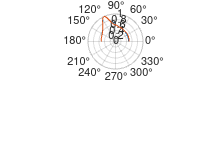

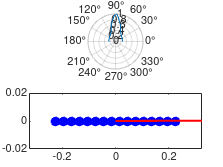

Index exceeds the number of array elements. Index must not exceed 50.

norm_pseudo_tot = abs(pseudo_tot);
norm_pseudo_tot = norm_pseudo_tot./max(norm_pseudo_tot, [], 2);
steps_axis = linspace(0,len/fs,steps);  %[s]

rotated_theta = mod(theta_axis*pi/180 + pi/2, 2*pi);

%[X,Y] = pol2cart(rotated_theta,);

vid = VideoWriter("polar_doa","Motion JPEG 2000");
vid.FrameRate = 20;
open(vid);
f = figure(200);
f.WindowState = "maximized";
for i = 1:steps
    subplot(2,1,1)
    polarplot(rotated_theta, norm_pseudo_tot(i,:));
    hold on
    %%%Data %%%%
    resultant_direction = theta(i);
    resultant_length = 0.9;
    %%%%arrow head %%%%
    arrowhead_length    = resultant_length/15; % arrow head length relative to resultant_length
    num_arrowlines = 100;
    arrowhead_angle = deg2rad(30); % degrees
    %%%%arrow tip coordinates %%%%
    t1 = repmat(resultant_direction,1,num_arrowlines);
    r1 = repmat(resultant_length,1,num_arrowlines);
    %%%%arrow base coordinates %%%%
    b = arrowhead_length.*tan(linspace(0,arrowhead_angle,num_arrowlines/2));
    theta = atan(b./(resultant_length-arrowhead_length));
    pre_t2 = [th, -the];
    r2 = (resultant_length-arrowhead_length)./cos(pre_t2);
    t2 = t1(1)+pre_t2;
    %%%%plot %%%%
    figure(1)
    polarplot([t1(1) t1(1)],[0 r1(1)-0.9*arrowhead_length],'r','linewidth',3)
    polarplot([t1; t2],[r1; r2],'r')
    titleStr = ['Pseudo spectrum for window #' num2str(i), ' time : ', num2str(i*len/(steps*fs)), ' s' ];
    title(titleStr);
    hold off
    subplot(2,1,2)
    plot(linspace(-L/2,L/2,M),zeros(1,M),'LineStyle','none','Color','b','Marker', 'o', 'MarkerSize', 2, 'LineWidth', 5, 'AutoScaleFactor', 0.7);
    xlim([-(L/2+0.1),L/2+0.1]);
    xlim([-(L/2+0.1),L/2+0.1]);
    hold on
    quiver(0,0,cos(theta(i)*pi/180),sin(theta(i)*pi/180),'LineStyle','-','Color','r','LineWidth',1.5)
    hold off
    frame = getframe(200);
    writeVideo(vid, frame);
    drawnow limitrate
end

close(vid);

## Other plots

figure();
subplot(2,1,1);
imagesc(steps_axis,theta_axis, norm_pseudo_tot');
ylabel("DOA[degs]");
xlabel("time [s]");
title("Averaged Normalized Pseudo Spectrum");

subplot(2,1,2);
plot(steps_axis, theta);
ylabel("Angle of arrival [deg]");
xlabel("time [s]");
title("Angles of arrival");

## Animation - To do

% 1st snippets
%{
rho = sin(2*theta_axis*pi/180); % Corresponding radial distances

% Calculate x and y components of vectors
x = rho.* cos(theta*pi/180); % x component
y = rho.* sin(theta*pi/180); % y component

% Calculate arrow lengths (optional)
arrow_length = 0.1; % Adjust arrow length as needed
dx = arrow_length * cos(theta);
dy = arrow_length * sin(theta);

% Plot arrows using quiver function
hold on;
quiver(theta_axis, rho, dx, dy, 0, 'Color', 'r', 'LineWidth', 2);
hold off; 
%}

Plot quiver plot

% Calculate x and y components of vectors
x = cos(theta*pi/180); % x component
y = sin(theta*pi/180); % y component

figure();
quiver(steps_axis', zeros(size(steps_axis)), x, y);%, 'Color', 'b', 'LineStyle', '--', 'AutoScaleFactor', 0.5);
xlabel('Time [s]');
ylabel('Direction estimation from the origin');
title('Time Evolution of Angle of Arrival');

%set(gca, 'XLim', [min(steps_axis), max(steps_axis)], 'YLim', [-1.2, 1.2], 'LineWidth', 1.5, 'TickLength', [0.02, 0.02]);
grid on;